clear;
A = 1100;
T = readtable("ランダム波形.csv");

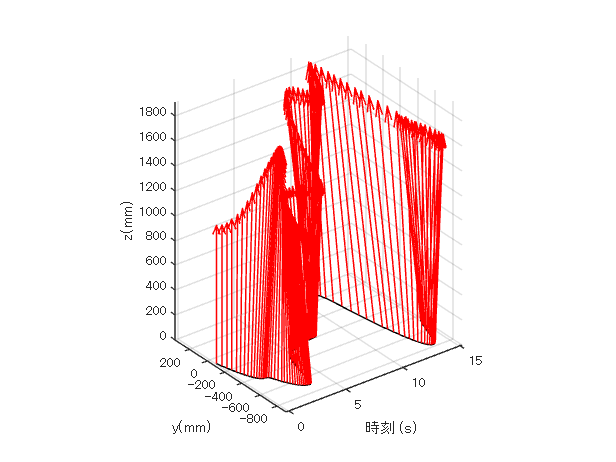

N = 151;
t = T.time_s_(1:N);
extend = T.stockLeftExtendPos_1cm_(1:N) * 100;
slider = T.stockLeftSliderPos_1cm_(1:N) * 100;
tilt = T.tiltLeft(1:N);

yground = slider;
zground = t*0;

yhandle = slider + (A + extend).*sin(-tilt/180*pi);
zhandle = (A + extend).*cos(-tilt/180*pi);

figure;
plot3(t*100, yground, zground, Color='black');
hold on;
% plot3(t*100, yhandle, zhandle, Color='black');
xlabel('時刻 (s)');
xticks([0 500 1000 1500]);
xticklabels({'0','5','10','15'});
ylabel('y(mm)');
zlabel('z(mm)');
grid on;
axis equal;
% ylim([-1000, 400]);
% zlim([0,100]);
for idx = 1:N
    quiver3(t(idx)*100, yground(idx), zground(idx), 0, sin(-tilt(idx)/180*pi), cos(-tilt(idx)/180*pi), A + extend(idx), Color='red', LineWidth=1);
    % pause(0.1);
end

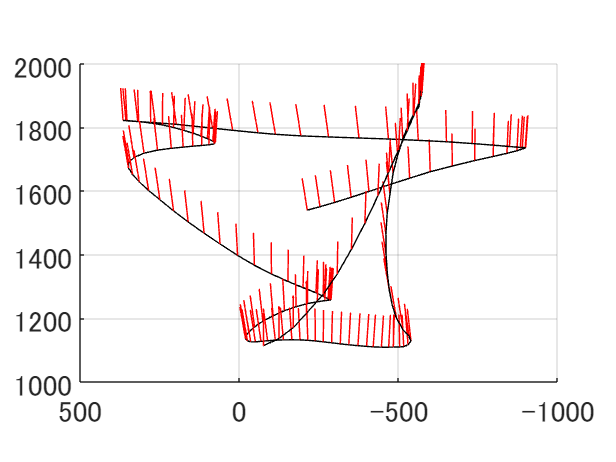


figure;
plot3(t*100, yground, zground, Color='black');
hold on;
% plot3(t*100, yhandle, zhandle, Color='black');
xlabel('時刻 (s)');
xticks([0 500 1000 1500]);
xticklabels({'0','5','10','15'});
% ylabel('y(mm)');
% zlabel('z(mm)');
grid on;
axis equal;
% ylim([-500, 500]);
% zlim([0,1400]);
plot3(t*100, yhandle, zhandle, Color='black');
for idx = 1:N
    % quiver3(t(idx)*100, yground(idx), zground(idx), 0, sin(-tilt(idx)/180*pi), cos(-tilt(idx)/180*pi), A + extend(idx), Color='red', LineWidth=1);
    % quiver3(t(idx)*100, yhandle(idx), zhandle(idx), 0, sin(-tilt(idx)/180*pi), cos(-tilt(idx)/180*pi), 50, Color='red', LineWidth=1);
    quiver3(t(idx)*100, yhandle(idx), zhandle(idx), 0, sin(-tilt(idx)/180*pi), cos(-tilt(idx)/180*pi), 100, Color='red', LineWidth=1);
    view(-90, 0);
    ylim([-1000, 500]);
    zlim([1000,2000]);
    ax = gca;
    ax.FontSize = 20;
    % title('平地軌跡');
    pause(0.1);
end
ax = gca;
ax.FontSize = 20;



clear;
A = 1100;
T = readtable("平地波形.csv");

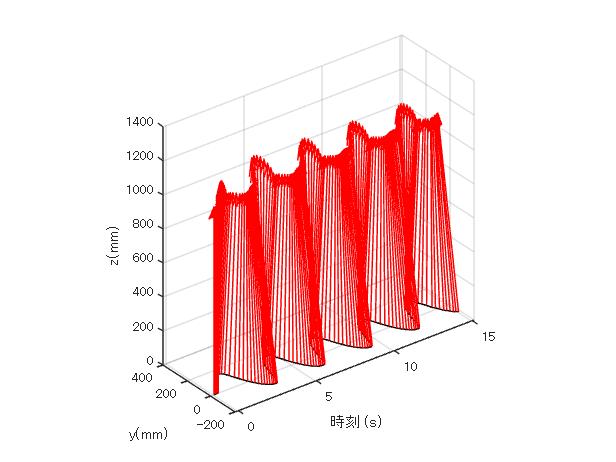

N = 151;
t = T.time_s_(1:N);
extend = T.leftExtend_mm_(1:N) * 100;
slider = T.stockLeftSlider_mm_(1:N) * 100;
tilt = T.tiltLeft(1:N);

yground = slider;
zground = t*0;

yhandle = slider + (A + extend).*sin(-tilt/180*pi);
zhandle = (A + extend).*cos(-tilt/180*pi);

figure;
plot3(t*100, yground, zground, Color='black');
hold on;
% plot3(t*100, yhandle, zhandle, Color='black');
xlabel('時刻 (s)');
xticks([0 500 1000 1500]);
xticklabels({'0','5','10','15'});
ylabel('y(mm)');
zlabel('z(mm)');
grid on;
axis equal;
ylim([-200, 400]);
zlim([0,1400]);
for idx = 1:N
    quiver3(t(idx)*100, yground(idx), zground(idx), 0, sin(-tilt(idx)/180*pi), cos(-tilt(idx)/180*pi), A + extend(idx), Color='red', LineWidth=1);
    % pause(0.1);
end

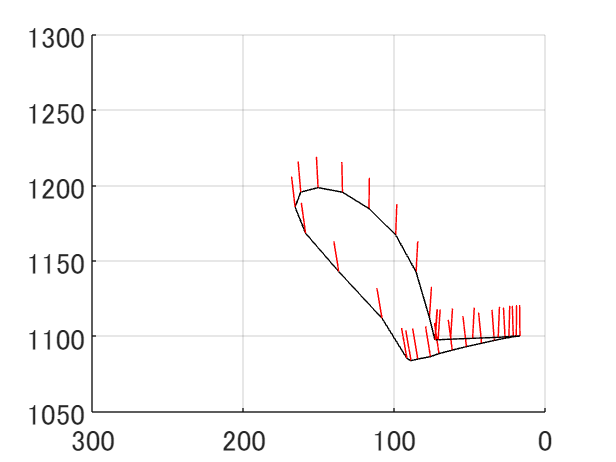


figure;
plot3(t*100, yground, zground, Color='black');
hold on;
% plot3(t*100, yhandle, zhandle, Color='black');
xlabel('時刻 (s)');
xticks([0 500 1000 1500]);
xticklabels({'0','5','10','15'});
% ylabel('y(mm)');
% zlabel('z(mm)');
grid on;
axis equal;
ylim([-500, 500]);
zlim([0,1400]);
plot3(t(16:46)*100, yhandle(16:46), zhandle(16:46), Color='black');
for idx = 16:46
    % quiver3(t(idx)*100, yground(idx), zground(idx), 0, sin(-tilt(idx)/180*pi), cos(-tilt(idx)/180*pi), A + extend(idx), Color='red', LineWidth=1);
    % quiver3(t(idx)*100, yhandle(idx), zhandle(idx), 0, sin(-tilt(idx)/180*pi), cos(-tilt(idx)/180*pi), 50, Color='red', LineWidth=1);
    quiver3(t(idx)*100, yhandle(idx), zhandle(idx), 0, sin(-tilt(idx)/180*pi), cos(-tilt(idx)/180*pi), 20, Color='red', LineWidth=1);
    view(-90, 0);
    ylim([0, 300]);
    zlim([1050,1300]);
    ax = gca;
    ax.FontSize = 20;
    % title('平地軌跡');
    pause(0.1);
end
ax = gca;
ax.FontSize = 20;

% title('平地軌跡');


T = readtable("中勾配波形.csv");

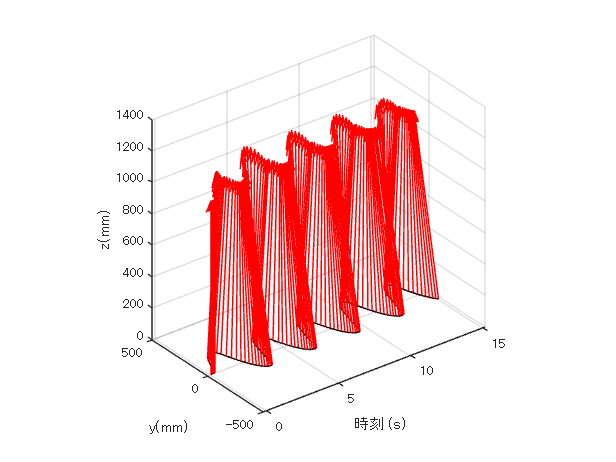

t = T.time_s_(1:N);
extend = T.stockLeftExtendPos_1cm_(1:N) * 10;
slider = T.stockLeftSliderPos_1cm_(1:N) * 10;
tilt = T.tiltLeft(1:N);

yground = slider;
zground = t*0;

yhandle = slider + (A + extend).*sin(-tilt/180*pi);
zhandle = (A + extend).*cos(-tilt/180*pi);

figure;
plot3(t*100, yground, zground, Color='black');
hold on;
% plot3(t*100, yhandle, zhandle, Color='black');
xlabel('時刻 (s)');
xticks([0 500 1000 1500]);
xticklabels({'0','5','10','15'});
ylabel('y(mm)');
zlabel('z(mm)');
grid on;
axis equal;
ylim([-500, 500]);
zlim([0,1400]);
for idx = 1:N
    quiver3(t(idx)*100, yground(idx), zground(idx), 0, sin(-tilt(idx)/180*pi), cos(-tilt(idx)/180*pi), A + extend(idx), Color='red', LineWidth=1);
    % pause(0.1);
end

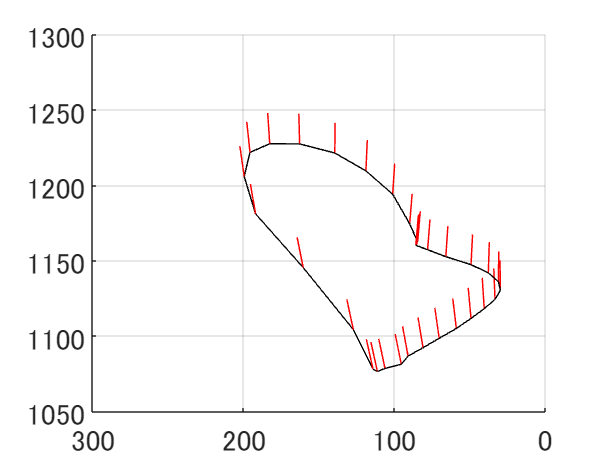


figure;
plot3(t*100, yground, zground, Color='black');
hold on;
% plot3(t*100, yhandle, zhandle, Color='black');
xlabel('時刻 (s)');
xticks([0 500 1000 1500]);
xticklabels({'0','5','10','15'});
% ylabel('y(mm)');
% zlabel('z(mm)');
grid on;
axis equal;
ylim([-200, 400]);
zlim([0,1400]);
plot3(t(16:46)*100, yhandle(16:46), zhandle(16:46), Color='black');
for idx = 16:46
    % quiver3(t(idx)*100, yground(idx), zground(idx), 0, sin(-tilt(idx)/180*pi), cos(-tilt(idx)/180*pi), A + extend(idx), Color='red', LineWidth=1);
    % quiver3(t(idx)*100, yhandle(idx), zhandle(idx), 0, sin(-tilt(idx)/180*pi), cos(-tilt(idx)/180*pi), 50, Color='red', LineWidth=1);
    quiver3(t(idx)*100, yhandle(idx), zhandle(idx), 0, sin(-tilt(idx)/180*pi), cos(-tilt(idx)/180*pi), 20, Color='red', LineWidth=1);
    view(-90, 0);
    ylim([0, 300]);
    zlim([1050,1300]);
    % pause(0.1);
    % title('中勾配軌跡');
end
% title('中勾配軌跡');
ax = gca;
ax.FontSize = 20;

T = readtable("急勾配波形.csv");

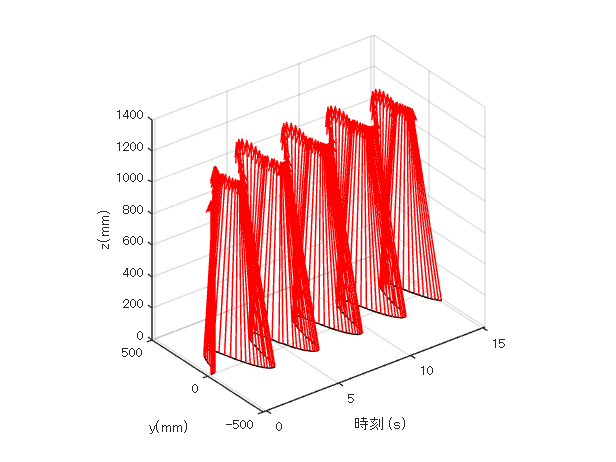

t = T.time_s_(1:N);
extend = T.stockLeftExtendPos_1cm_(1:N) * 10;
slider = T.stockLeftSliderPos_1cm_(1:N) * 10;
tilt = T.tiltLeft(1:N);

yground = slider;
zground = t*0;

yhandle = slider + (A + extend).*sin(-tilt/180*pi);
zhandle = (A + extend).*cos(-tilt/180*pi);

figure;
plot3(t*100, yground, zground, Color='black');
hold on;
% plot3(t*100, yhandle, zhandle, Color='black');
xlabel('時刻 (s)');
xticks([0 500 1000 1500]);
xticklabels({'0','5','10','15'});
ylabel('y(mm)');
zlabel('z(mm)');
grid on;
axis equal;
ylim([-500, 500]);
zlim([0,1400]);
for idx = 1:N
    quiver3(t(idx)*100, yground(idx), zground(idx), 0, sin(-tilt(idx)/180*pi), cos(-tilt(idx)/180*pi), A + extend(idx), Color='red', LineWidth=1);
    % pause(0.1);
end

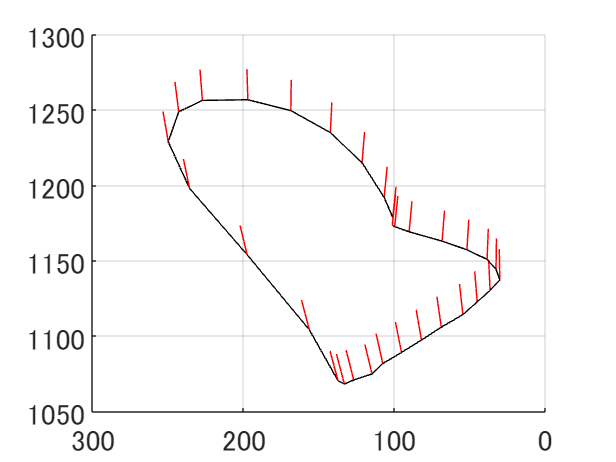


figure;
plot3(t*100, yground, zground, Color='black');
hold on;
% plot3(t*100, yhandle, zhandle, Color='black');
xlabel('時刻 (s)');
xticks([0 500 1000 1500]);
xticklabels({'0','5','10','15'});
% ylabel('y(mm)');
% zlabel('z(mm)');
grid on;
axis equal;
ylim([-200, 400]);
zlim([0,1400]);
plot3(t(16:46)*100, yhandle(16:46), zhandle(16:46), Color='black');
for idx = 16:46
    % quiver3(t(idx)*100, yground(idx), zground(idx), 0, sin(-tilt(idx)/180*pi), cos(-tilt(idx)/180*pi), A + extend(idx), Color='red', LineWidth=1);
    % quiver3(t(idx)*100, yhandle(idx), zhandle(idx), 0, sin(-tilt(idx)/180*pi), cos(-tilt(idx)/180*pi), 50, Color='red', LineWidth=1);
    quiver3(t(idx)*100, yhandle(idx), zhandle(idx), 0, sin(-tilt(idx)/180*pi), cos(-tilt(idx)/180*pi), 20, Color='red', LineWidth=1);
    view(-90, 0);
    ylim([0, 300]);
    zlim([1050,1300]);
    % title('急勾配軌跡');
    % pause(0.1);
end
% title('急勾配軌跡');
ax = gca;
ax.FontSize = 20;